Changes made and functions implemented:

- KL.m created. Implements the KL-divergence objective function for pdco.

- PDCO_KL.m created. Given inputs A, b, mu, lmda, and delta, runs the pdco algorithm in pdco.m for the KL.m objective function. 

- Modified lines 509, 1111, and 1366 in pdco.m to allow pdObj to take two inputs.

- Commented out lines 370-373 and 1376-1378 in pdco.m to avoid interruptions to the algorithm's execution 

- Commented out print statement on line 513 of pdco.m

print = 0; % set print = 1 to obtain printed output from pdco

**Below is example usage of PDCO_KL() on some synthetic data (i.i.d Gaussian matrix):**

A = rand(100, 400); % generate A
[m, n] = size(A);
mu = ones(n,1) / n; % generate mu

% generate ground truth
xsol = ones(n,1) / n;
xsol(180:200,:) = 5;
xsol(300:302,:) = 2;
xsol = xsol ./ sum(xsol);

b = A * xsol; % generate b

lmda = 1e-8;
delta = 1e-3;

[x, y, z, inform] = PDCO_KL(A, b, mu, lmda, delta, print);

disp('Sum of entries of x:')

Sum of entries of x:


disp(sum(x)); 

    1.0000



disp('Res:')

Res:


disp(norm(A*x - b));

   2.9949e-07



disp('RMSE:')

RMSE:


disp(norm(x - xsol)/sqrt(n));

   1.8985e-04



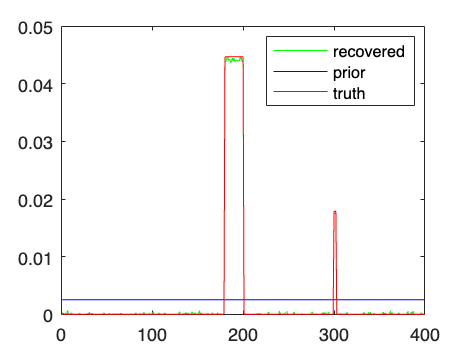


x_ = 1:n;
figure
plot(x_ ,x,'g-',x_, mu,'b', x_, xsol,'r')
legend('recovered', 'prior', 'truth')

## Testing PDCO on data

We test PDCO_KL.m on 4 datasets:

- PhysicsData.mat

- synthetic_data.mat

- rho-meson_testproblem.mat

- synthetic-UEG_testproblem.mat

### **PhysicsData**

data = load('data/PhysicsData.mat'); 
A = data.A;
b = data.b;
b = b'; % reshape
x0 = data.x0;
x0 = x0'; % reshape

[m, n] = size(A);
mu = ones(n, 1) / n; % uniform prior

% code to find the best lmda by comparing |x-x0|/sqrt(n)

lmdas = logspace(-16, -2, 50);
delta = 10e-4;

min_rmse = inf;
best_lmda = NaN;

for i = 1:length(lmdas)
    lmda = lmdas(i);
    x = PDCO_KL(A, b, mu, lmda, delta, print);
    rmse = norm(x0 - x)/sqrt(n);
    if rmse < min_rmse
        min_rmse = rmse;
        best_lmda = lmda;
    end
end

% it seems that the best lmda is the smallest one tested
fprintf('Best: lmbda = (%f) | RMSE: = %f\n', best_lmda, min_rmse); 

Best: lmbda = (0.000000) | RMSE: = 0.000784


#### RMSE, Residual, and visualization

[x, y, z, inform] = PDCO_KL(A, b, mu, best_lmda, delta, print);

disp('PhysicsData');

PhysicsData


disp('Sum of entries of x:')

Sum of entries of x:


disp(sum(x)); 

    1.0024



disp('Res:')

Res:


disp(norm(A*x - b));

    0.0832



disp('RMSE:')

RMSE:


disp(norm(x - x0)/sqrt(n));

   7.8409e-04



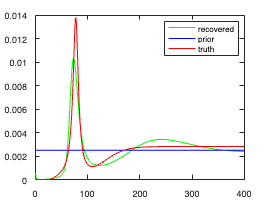


x_ = 1:n;
figure
plot(x_ ,x,'g-',x_, mu,'b', x_, x0,'r')
legend('recovered', 'prior', 'truth')

### **Synthetic data**

data = load('data/synthetic_data.mat');
A = data.A;
b = data.b;
b = b'; % reshape
x0 = data.x;
x0 = x0'; % reshape

[m, n] = size(A);
mu = ones(n, 1) / n; % uniform prior

As seen in the below code, x0 is not normalized and so we must make a choice to either normalize b by sum(x0) or by b(1) (see Section 8.2 of notes). In this case, lets normalize by sum(x0).

sum(x0)

ans = single
6.3281

b(1)

ans = 6.4728

% Normalization
nrmlzd_b = double(b ./ sum(x0));

% code to find the best lmda by comparing |x-x0|/sqrt(n)

lmdas = logspace(-15, -2, 50);
delta = 10e-4;

min_rmse = inf;
best_lmda = NaN;

for i = 1:length(lmdas)
    lmda = lmdas(i);
    x = PDCO_KL(A, nrmlzd_b, mu, lmda, delta, print);
    x = sum(x0) * x; % We "undo" the normalization in the solution 
    rmse = norm(x0 - x)/sqrt(n);
    if rmse < min_rmse
        min_rmse = rmse;
        best_lmda = lmda;
    end
end

fprintf('Best: lmbda = (%f) | RMSE: = %f\n', best_lmda, min_rmse); 

Best: lmbda = (0.000002) | RMSE: = 0.001633


#### RMSE, Residual, and visualization

[x, y, z, inform] = PDCO_KL(A, nrmlzd_b, mu, best_lmda, delta, print);
x = sum(x0) * x; % We "undo" the normalization in the solution 

disp('Synthetic data');

Synthetic data


disp('Sum of entries of x:')

Sum of entries of x:


disp(sum(x)); 

    6.3280



disp('Res:')

Res:


disp(norm(A*x - b));

    0.0111



disp('RMSE:')

RMSE:


disp(norm(x - x0)/sqrt(n));

    0.0016



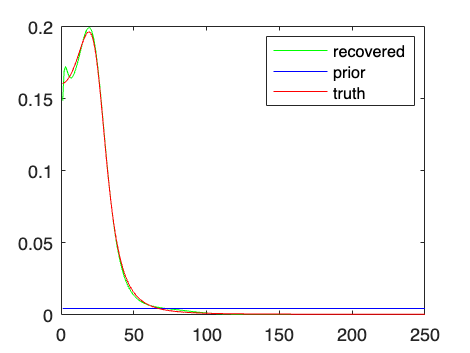


x_ = 1:n;
figure
plot(x_ ,x,'g-',x_, mu,'b', x_, x0,'r')
legend('recovered', 'prior', 'truth')

### Synthetic UEG

data = load('data/synthetic-UEG_testproblem.mat');
A = data.A;
[m, n] = size(A);

b = data.b_avg;
b = b';
x0 = data.x; % already normalized
x0 = x0'; 
mu = data.mu; % prior provided
mu = double(mu'); % was single precision

% code to find the best lmda by comparing |x-x0|/sqrt(n)

lmdas = logspace(-15, -2, 100);
delta = 10e-4;

min_rmse = inf;
best_lmda = NaN;

for i = 1:length(lmdas)
    lmda = lmdas(i);
    x = PDCO_KL(A, b, mu, lmda, delta, print);
    rmse = norm(x0 - x)/sqrt(n);
    if rmse < min_rmse
        min_rmse = rmse;
        best_lmda = lmda;
    end
end

% it seems that the best lmda is the smallest one tested
fprintf('Best: lmbda = (%f) | RMSE: = %f\n', best_lmda, min_rmse); 

Best: lmbda = (0.000000) | RMSE: = 0.005658


#### RMSE, Residual, and visualization

[x, y, z, inform] = PDCO_KL(A, b, mu, best_lmda, delta, print);

xsum = sum(x);
disp('Synthetic UEG');

Synthetic UEG


disp('Sum of entries of x:')

Sum of entries of x:


disp(xsum); 

    0.9848



disp('Res:')

Res:


disp(norm(A*x - b));

    0.0017



disp('RMSE:')

RMSE:


disp(norm(x - x0)/sqrt(n));

    0.0057



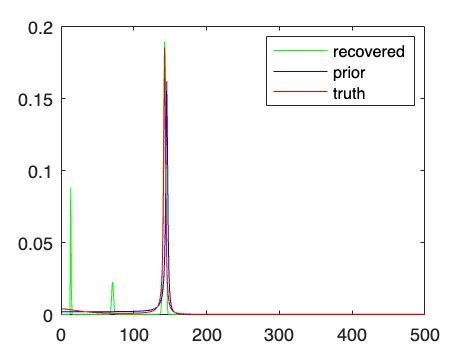

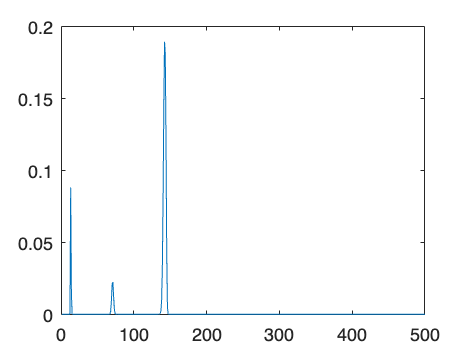


x_ = 1:n;
figure
plot(x_ ,x,'g-',x_, mu,'b', x_, x0,'r')
legend('recovered', 'prior', 'truth')

### Rho-meson

disp('Rho-meson');

Rho-meson


data = load('data/rho-meson_testproblem.mat'); % the same as PhysicsData?
A = data.A;
b = data.b_avg;
x0 = data.x;
mu = data.mu; % prior provided

s = 90.6409

Note: Rho-meson appears to be the same as PhysicsData.